clear all;
%hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_10_40_31_70mm\2022_12_21_10_26_10.txt';
hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_11_23_57_70mmWade\2022_12_21_11_12_18.txt';

file = fileread(hexa_file_name);
hexa_string_all(1,:) = strfind(file,"X: ");
hexa_string_all(2,:) = strfind(file,", Y");
hexa_string_all(3,:) = strfind(file,"Y: ");
hexa_string_all(4,:) = strfind(file,", Z");
hexa_string_all(5,:) = strfind(file,"Z: ");
hexa_string_all(6,:) = strfind(file,", U");
hexa_string_all(7,:) = strfind(file,"U: ");
hexa_string_all(8,:) = strfind(file,", V");
hexa_string_all(9,:) = strfind(file,"V: ");
hexa_string_all(10,:) = strfind(file,", W");
hexa_string_all(11,:) = strfind(file,"W: ");
for i=1:size(hexa_string_all,1)
    hexa_string(i,:) = hexa_string_all(i,2:2:end);
end
hexa_string(12,:) = strfind(file,", T");
 
for j=1:size(hexa_string,2)
    for i=1:size(hexa_string,1)/2
        hexa_pos(i,j) = double(string(file(hexa_string(i*2-1,j)+3:hexa_string(i*2,j)-1)));
    end
end
hexa_pos(1,:) = hexa_pos(1,:);
hexa_pos(2,:) = hexa_pos(2,:);
hexa_pos(3,:) = hexa_pos(3,:);
hexa_pos(4,:) = hexa_pos(4,:);
hexa_pos(5,:) = hexa_pos(5,:);
 
%sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_10_40_31_70mm\download\';
sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_11_23_57_70mmWade\download\';

[sparseQ, sparseN, sparseD] = deal([]);
sli_files = dir([sli_file_path '*.unk']);
for i=1:length(sli_files)
    [h,sli(i,:),m] = readAscImage([sli_file_path sli_files(i).name]);  
    
    sparse = [sli(i,:).sliData.Q(sli(i,:).sliData.sliID ~= 255, :)/1e3, sli(i,:).sliData.sliID(sli(i,:).sliData.sliID ~= 255, :)];
    N_s = sli(i,:).sliHeader.planeN;
    D_s = sli(i,:).sliHeader.planeD/1e3;
    
    sparseQ = [sparseQ; [sparse, i*ones(size(sparse, 1), 1)]];
    sparseN = [sparseN; [N_s, i*ones(size(N_s, 1), 1)]];
    sparseD = [sparseD; [D_s, i*ones(size(D_s, 1), 1)]];
end
hexa_pos(:,1:length(sli_files)) = hexa_pos(:,size(hexa_pos,2)-length(sli_files)+1:end) ;
%Cam rotation
best_angle_x = 18.27;
best_angle_y = -0.38;
best_angle_z = 0.2700;
pivot_point_ = 190*10^3; %um
c2x_y = 23*10^3;        %um
x2c_z = 22997;          %um
desired_distance = 30*10^3; %um
 
x_ray_pos = zeros(3,length(sli_files));
x_ray_pos(3,:) = pivot_point_;
for i=1:length(sli_files)
    R_hex = createRotationMatrix(hexa_pos(6,i),hexa_pos(5,i),hexa_pos(4,i));
    x_ray_pos(:,i) = R_hex * x_ray_pos(:,i);
    x_ray_pos(:,i) = x_ray_pos(:,i) + hexa_pos(1:3,i);
end



% Rotate and translate to "sensor frame"
for i=1:size(sli,1)
    temp = sli(i).sliData.Q'; 
    temp(4,:) = 1;
    sli_data_rot{i}.Q = temp;
    %sli_data_cen{i}.cen = sli(i).sliData.cen;
    T = [0 c2x_y (pivot_point_-desired_distance-x2c_z)]';
    %T = [0 c2x_y pivot_point-x2c_z]';
    R = createRotationMatrix(best_angle_z,best_angle_y,best_angle_x);
    P = [R T];
    sli_data_rot{i}.Q = P*sli_data_rot{i}.Q;
end

sli_data_hexa = sli_data_rot;
% Rotate and translate to "base frame"
for i=1:size(sli,1)
    sli_data_hexa{i}.Q(4,:) = 1;
    %R_hex = createRotationMatrix(-hexa_pos(6,i),-hexa_pos(5,i),-hexa_pos(4,i));
    R_hex = createRotationMatrix(hexa_pos(6,i),hexa_pos(5,i),hexa_pos(4,i));
    T_hex = [hexa_pos(1:3,i)];
    P_hex = [R_hex' T_hex];
    sli_data_hexa_rot{i}.Q = P_hex * sli_data_hexa{i}.Q;
end


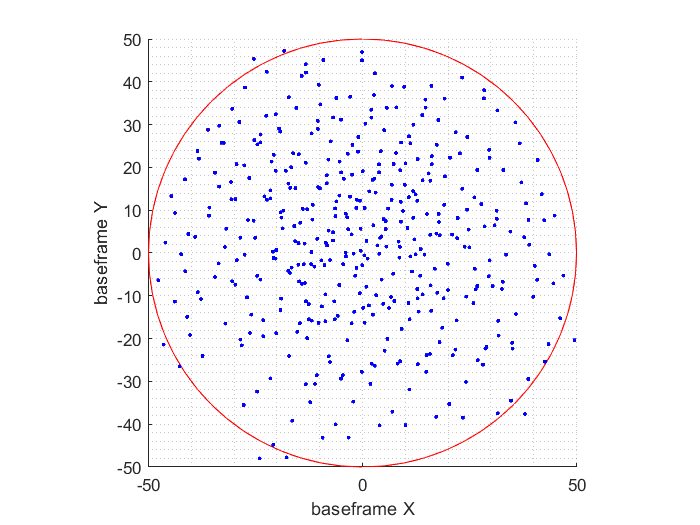



figure(4)
clf
hold on;
ij_range = 1:25; %[1 2];
for i=ij_range %:size(sli_data_hexa_rot,2)
%     plot3(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000,'.','color',colors(i,:))
    plot3(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000,'.r')
%     plot3(mean(sli_data_hexa_rot{i}.Q(1,:))/1000,mean(sli_data_hexa_rot{i}.Q(2,:))/1000,mean(sli_data_hexa_rot{i}.Q(3,:))/1000,'*','color',colors(i,:),'markersize',10)
end

grid minor;
%axis ij;
xlabel("baseframe X")
ylabel("baseframe Y")
zlabel("baseframe Z")
x = [];
y = [];
z = [];
for i=1:size(sli_data_hexa_rot,2)
    x = [x sli_data_hexa_rot{i}.Q(1,:)/1000];
    y = [y sli_data_hexa_rot{i}.Q(2,:)/1000];
    z = [z sli_data_hexa_rot{i}.Q(3,:)/1000];
end
hold on
circ_x = cosd(1:360);
circ_y = sind(1:360);
circ_r = 50;
plot3(circ_x*circ_r, circ_y*circ_r, mean(z)*ones(size(circ_x)), 'r')

axis equal
%xlim([-50, 50])

O_sparse = [-4.97106199398101	-23.3166644021243	25.9323627986420];
    
unit_vec_sparse = ...
[-0.288747648637093	    0.306293242445162	0.907088333647269	19; ...
-0.158749579397549	    0.489889012839238	0.857209032932166	24; ...
-0.109768703619059	    0.203271681156385	0.972949872987117	27; ...
-0.0907968144078339	    0.0381900376058185	0.995136904913618	29; ...
-0.00567908914511474	0.521497048049676	0.853234186388448	30; ...
0.0207666893788740	    0.386062644452971	0.922238786416089	32; ...
0.0437189127391662	    0.236202180725793	0.970719932055217	34; ...
0.171328431220356	    0.404572093780863	0.898313970496586	38; ...
0.193597326951717	    0.255385818084361	0.947258232436400	40; ...
0.360415150717705	    0.0970278401199079	0.927731921071384	48; ...
-0.132920541223632	    0.353306930817220	0.926016383417341	153; ...
0.0622579867034057	    0.0721187237278580	0.995451070007714	165; ...
0.319234128656939	    0.411526809366900	0.853659918394289	170; ...
0.212495249872407	    0.0913461994675134	0.972883158773192	171; ...
0.341601505721431	    0.261113540324678	0.902844466310762	173];

dist2plane = 35; draw = 0;
[Nref, target_cen, p2, p_xray, h_xray, pivot_point] = PIXLmodel(dist2plane);

%clf
%figure(6)


rot_xy = [];
rot_sparseQ = [];
for j = ij_range %1:length(hexa_pos)%29%1:30
    
    % Translation matrix

    %T = [1, 0, 0, pivot_point(1); 0, 1, 0, pivot_point(2); 0, 0, 1, pivot_point(3); 0, 0, 0, 1];

    % Rotation to align with base-frame
    best_angle_x = 18.27;
    best_angle_y = -0.38;
    best_angle_z = 0.2700;
        
    pivot_point_ = 190; %um
    c2x_y = 23;        %um
    x2c_z = 22997*1e-3; %um
    desired_distance = 30; %um

    Rc = createRotationMatrix(best_angle_z, best_angle_y, best_angle_x);
    Rc = [Rc, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    R = createRotationMatrix(hexa_pos(6,j),hexa_pos(5,j),hexa_pos(4,j));
    R = [R, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    %T_rot = [1, 0, 0, hexa_pos(1, j); 0, 1, 0, hexa_pos(2, j); 0, 0, 1, hexa_pos(3, j); 0, 0, 0, 1];
    %T_p2 = [1, 0, 0, p2(1); 0, 1, 0, p2(2); 0, 0, 1, p2(3); 0, 0, 0, 1];
    %T_base = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, h_xray(3); 0, 0, 0, 1];
    %pivot_point_r = (T_base^-1*T_p2*Rc*T_p2^-1*[pivot_point, 1]')'; 
    % c2x_y = 23%*10^3;        %um
    % x2c_z = 22.997;          %um
    %T_pivot = [1, 0, 0, pivot_point_r(1); 0, 1, 0, pivot_point_r(2); 0, 0, 1, pivot_point_r(3); 0, 0, 0, 1];
    T_pivot = [1, 0, 0, 0; 0, 1, 0, c2x_y; 0, 0, 1, (pivot_point_-desired_distance-x2c_z); 0, 0, 0, 1];
    T = [1, 0, 0, hexa_pos(1, j); 0, 1, 0, hexa_pos(2, j); 0, 0, 1, hexa_pos(3, j); 0, 0, 0, 1];
    
    %RT = R*T_rot*Rc*T_pivot^-1;
    
    %RT = T_pivot*R*T_pivot^-1*T_base^-1*T_p2*Rc*T_p2^-1;
    RT = T*R'*T_pivot*Rc;
    
    pos_rot = RT*[target_cen, 1]';
    pos_rot = pos_rot(1:3)';
    
    % Finding the delta-x-y coordinates of the rotations
    
    O_sparse_SLI = RT*[O_sparse, 1]';
    O_sparse_SLI = O_sparse_SLI(1:3)';
    
    sparseQ_coor = sparseQ(sparseQ(:, 5) == j, :);
    for k = 1:size(sparseQ_coor, 1)
        sparseQ_r = RT*[sparseQ_coor(k, 1:3), 1]';
        sparseQ_(k, 1:3) = sparseQ_r(1:3)';
        rsQ(k, :) = [sparseQ_(k, 1:3), sparseQ_coor(k, 4:5)];
        %rsQ_ = (sparseQ_(k, 1:3) - O_sparse_SLI)./norm(sparseQ_(k, 1:3) - O_sparse_SLI);
        %[rsQ_, ~] = line_plane_intersection(rsQ_, O_sparse_SLI, [0, 0, 1], target_cen);
        %[rsQ_, ~] = line_plane_intersection(rsQ_, O_sparse_SLI, [0, 0, 1], [0, 0, 235.1198]);
        %rsQ(k, :) = [rsQ_, sparseQ_coor(k, 4:5)];
    end
    
    rot_sparseQ = [rot_sparseQ; rsQ];
    
end
I_apriori = [];
for i = ij_range %1:size(hexa_pos, 2)
    I_sparse = reprojectSLI(O_sparse, unit_vec_sparse, p2, h_xray, pivot_point, target_cen, hexa_pos(4:6, i)', [0, 0, 0], 0);
    I_apriori = [I_apriori; [[I_sparse, i*ones(size(I_sparse, 1), 1)]]];
end

TargetCircle = drawCircle(50, [0, 0, mean(I_apriori(:, 3))], [0, 0, 1],'r', 2);


%plot3(I_apriori(:, 1),...
%      I_apriori(:, 2),...
%      I_apriori(:, 3), 'bo', 'LineWidth', 1.5)
hold on
plot3(rot_sparseQ(:, 1), rot_sparseQ(:, 2), rot_sparseQ(:, 3), 'b.')

plot3(TargetCircle(:, 1), TargetCircle(:, 2), TargetCircle(:, 3), 'r-')
view(0,90)
%axis equal
xlim([-50, 50])
ylim([-50, 50])